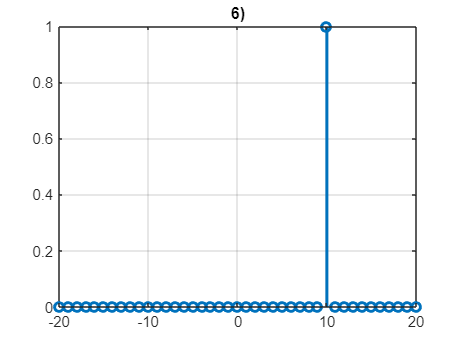

% 6)
clear; clc; close;
% Create the function Delta(k) that plots 𝛿[𝑛 − 𝑘] for any given ‘k’.
% The parameter ‘k’ should be considered as an input argument of the function. 
% For plotting use the'stem' command. Then, make an example of it.
Delta(10);

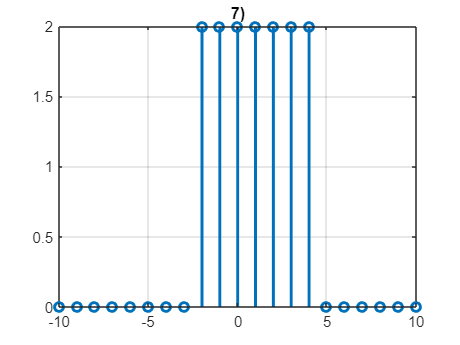

% 7)
clear; clc; close;
% reate the function Pulse(a,k0,k1) that plots
% 𝑎 ∗ 𝑢[𝑛 − 𝑘0]- 𝑎 ∗ 𝑢[𝑛 − 𝑘1] for any given constants 𝑎, 𝑘0, 𝑎𝑛𝑑 𝑘1.  
% Then, make the following example using the created function.
% 𝑥[𝑛]=2𝑢[𝑛−3]−2𝑢[𝑛−10]. 
Pulse(2, -2, 5);

function Delta(k)
    n = -2*abs(k):2*abs(k);
    y = zeros(1,length(n));
    index = n==k;
    y(index) = 1;
    stem(n, y, 'Linewidth', 2); grid; title('6)')
end


function Pulse(a, k0, k1)
    n = -2*abs(max(k0,k1)):2*abs(max(k0,k1));
    y1 = zeros(1,length(n));
    for index = 1:length(n)
        if n(index) >= k0
            y1(index) = a;
        end
    end
    y2 = zeros(1,length(n));
    for index = 1:length(n)
        if n(index) >= k1
            y2(index) = a;
        end
    end
    y = y1 - y2;
    stem(n, y, 'Linewidth', 2); grid; title('7)');
end